# **Heightmap Generation Using Diamond-Square Algorithm**

The [diamond-square algorithm](https://en.wikipedia.org/wiki/Diamond-square_algorithm) is a method for generating [heightmaps](https://en.wikipedia.org/wiki/Heightmap) for computer graphics and can be used to [procedurally](https://en.wikipedia.org/wiki/Procedural_textures) generate realistic landscapes. It is also known as the random midpoint displacement fractal, the cloud fractal or the plasma fractal.

## Clean Workspace

clc
clear
close all

## Parameter Initialization

n = 8;
p = (2^n)+1;
a = zeros(p);
int = rand(1);
rng(1)
chunk_size = p-1;
h = 1; % [0 1] Closer to zero results in smoother landscapes
range = 1; 
a(1, 1) = int;
a(end, 1) = int; 
a(1, end) = int;
a(end, end) = int;

## Heightmap Generation

For each square in the array, set the midpoint of that square to be the average of the four corner points plus a random value.

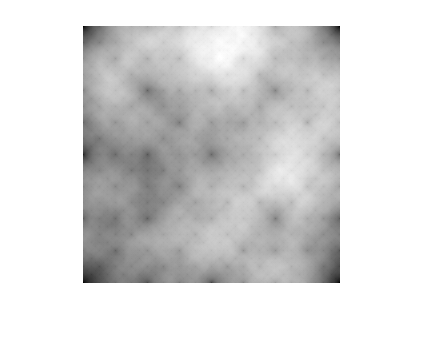

while chunk_size > 1
    half = chunk_size/2;
    a = square_step(chunk_size, half, p, a, range);
    a = diamond_step(chunk_size, half, p, a, range);
    chunk_size = chunk_size/2;
    range = range*h*2^(-h);
end

norm_a = a-min(a(:));
norm_a = norm_a./max(norm_a(:));
hmap = mat2gray(norm_a,[0 1]);
figure(1)
imshow(hmap)

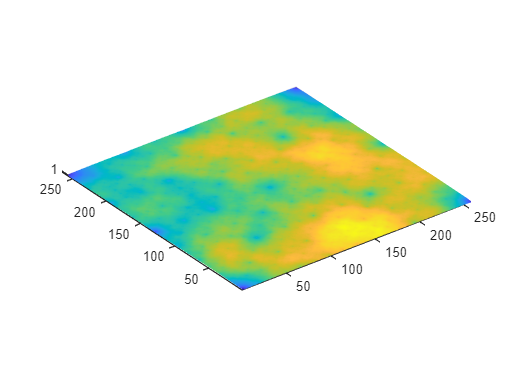

% imwrite(hmap,'Heightmap.bmp')
figure(2)
mesh(a)
axis equal

## Square Step

For each diamond in the array, set the midpoint of that diamond to be the average of the four corner points plus a random value.

function a = square_step(chunk_size, half, p, a, range)
    for y = 1:chunk_size:p
        for x = 1:chunk_size:p
            if x < p && y < p
                a(y+half, x+half) = ((a(y, x) + a(y, x+chunk_size)...
                    + a(y+chunk_size, x) + a(y+chunk_size, x+chunk_size))/4)...
                    + rand(1)*range;
            else
            end
        end
    end
end

## Diamond Step

function a = diamond_step(chunk_size, half, p, a, range)
    for y = 1:half:p
        for x = 1:half:p
            if any(a(y, x))
            elseif x==1 && y~=p
                a(y, x) = ((a(y-half, x) + a(y, x+half)...
                    + a(y+half, x))/3) + rand(1)*range;
            elseif y==1 && x~=p
                a(y, x) = ((a(y, x-half) + a(y, x+half)...
                    + a(y+half, x))/3) + rand(1)*range;
            elseif x==p && y~=1
                a(y, x) = ((a(y-half, x) + a(y, x-half) ...
                    + a(y+half, x))/3) + rand(1)*range;
            elseif y==p && x~=1
                a(y, x) = ((a(y-half, x) + a(y, x-half)...
                    + a(y, x+half))/3) + rand(1)*range;
            else
                a(y, x) =  ((a(y-half, x) + a(y, x-half)...
                    + a(y, x+half) + a(y+half, x))/4) + rand(1)*range;
            end
        end
    end
end